# EXERCISE B -- GUIDED STIFFNESS-METHOD TUTORIAL

Determine the reactions at nodes 1 and 4. The portal is 2 m wide and 3 m high. Its bases are pins; its upper beam-to-column connections are rigid. A horizontal uniform load of 6 kN/m acts rightward along the entire left column.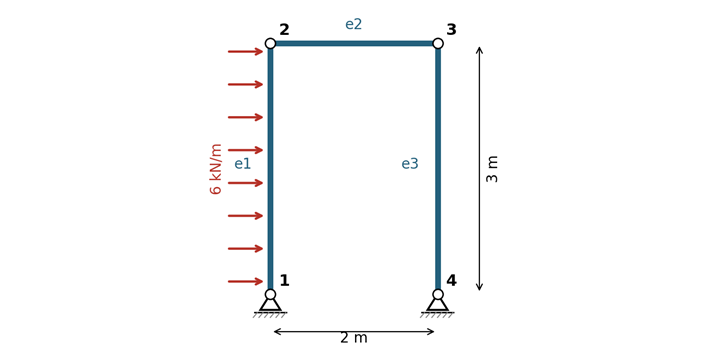

## 0. Prepare the workspace and display options

clear removes previous variables; clc clears the Command Window; close all closes earlier figures. Execute this section once at the START. showMatrices controls intermediate output, makePlots controls visualization, and deformationScale=0 requests automatic visual magnification. These switches do not change the structural solution.

clear; clc; close all;
format short g;
showMatrices = true;   % Show element matrices and assembled equations.
makePlots = true;      % Set false for numerical calculations only.
deformationScale = 0;  % Zero selects an automatic visual magnification.

## Exercise statement and modeling interpretation

Nodes follow the figure: 1 left base, 2 left top, 3 right top, 4 right base. Elements: 1 = left column (up), 2 = beam (right), 3 = right column (down). The nonsequential dofMap below preserves the figure's DOF NUMBERS.

## 1. Define material and section properties

PURPOSE: establish axial rigidity EA and bending rigidity EI. Convert 200 GPa to 200000 N/mm^2. All dimensions are entered in mm. A is cross-sectional area in mm^2; I is the second moment of area in mm^4 about the out-of-plane bending axis. Every member has the same properties, so scalar E, A and I are sufficient for these exercises.

## 2. Define node coordinates and member connectivity

PURPOSE: describe the frame as joints connected by straight members. Each row of nodes is [x y] in mm, and its row number is the node number. Each row of elements is [i j], and its row number is the element number. The i->j order defines local axes and signs; it does not change the physical frame if all associated local quantities are transformed consistently.

## 3. Associate each motion with a global equation number

PURPOSE: connect physical nodal motions with positions in the solution vector. dofMap(n,:)=[index_ux index_uy index_theta] at node n. For example, d(dofMap(n,1)) returns node n's horizontal displacement. Every global index appears once. Connectivity uses NODE numbers, whereas stiffness assembly uses DOF numbers: do not confuse these two lists.

## 4. Define the support restraints

PURPOSE: distinguish a support pin from a rigid member-to-member joint. At nodes 1 and 4, constrain ONLY translations: DOFs 9,10,11,12 are zero. Base rotations 7 and 8 remain unknown, leaving eight free DOFs. Only one member meets each base, so a free base rotation enforces zero end moment without a separate element-end release formulation. At upper nodes 2 and 3, connected members share one rotation: rigid joints. Constraining base rotations would change this model to fixed supports.

## 5. Define loads and their coordinate directions

PURPOSE: describe the physical member load before converting it to nodal loads. There are no concentrated point loads. The left column carries 6 kN/m to the RIGHT, equivalent to 6 N/mm. Its local x points UP and its local y points LEFT, so local qy=-6 N/mm. Local axial loading qx is zero. Stage 8 gives global horizontal end forces of +9 kN each and equivalent end moments of -4.5 kN*m at the lower end and +4.5 kN*m at the upper end. These end moments are necessary even though the actual base is a pin: the pin's zero physical end moment is recovered after solving the frame.

EXERCISE B: reactions at pin supports 1 and 4


Global signs: right/up/CCW positive. Internal units: N, mm, rad.


## 6. Determine element lengths, orientations and global DOF lists

PURPOSE: turn geometry into element information. For a member i->j: dx=xj-xi; dy=yj-yi; L=sqrt(dx^2+dy^2); c=dx/L; s=dy/L. c and s are direction cosines. Local x points from i to j; local y is 90 degrees counterclockwise from local x. edofs gives the six GLOBAL indices of this element in endpoint order. elementData stores one record per member, with named fields.


Element 1: node 1 -> 2, L = 3000 mm, c = 0.0, s = 1.0


Element DOFs: 11 12 8 1 2 3 



Element 2: node 2 -> 3, L = 2000 mm, c = 1.0, s = 0.0


Element DOFs: 1 2 3 4 5 6 



Element 3: node 3 -> 4, L = 3000 mm, c = 0.0, s = -1.0


Element DOFs: 4 5 6 9 10 7 


## 7. Calculate the local stiffness and transform it to global axes

PURPOSE: combine axial and bending behavior in a common coordinate system. The included frameElement function gives the full 6-by-6 matrix. Its axial terms contain EA/L. Its bending terms contain 12EI/L^3, 6EI/L^2, 4EI/L and 2EI/L. A frame transmits bending moments as well as axial forces; a truss model would omit the bending behavior.

ELEMENT RELATION without member loading: qLocalEnd=kLocal*dLocal. dLocal=T*dGlobal; qGlobalEnd=T'*qLocalEnd. Consequently kGlobal=T'*kLocal*T. For each node [u;v]=[c s;-s c]*[ux;uy]; the z rotation is unchanged. Transforming forces with T' preserves virtual work in the two systems. MATLAB .' is transpose without complex conjugation.


ELEMENT 1 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
   6.4533e+05            0            0  -6.4533e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
  -6.4533e+05            0            0   6.4533e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10



Transformation T:
     0     1     0     0     0     0
    -1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0     1     0
     0     0     0    -1     0     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
        26667            0       -4e+07       -26667            0       -4e+07
            0   6.4533e+05            0            0  -6.4533e+05            0
       -4e+07            0        8e+10        4e+07            0        4e+10
       -26667            0        4e+07        26667            0        4e+07
            0  -6.4533e+05            0            0   6.4533e+05            0
       -4e+07            0        4e+10        4e+07            0        8e+10




ELEMENT 2 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
     9.68e+05            0            0    -9.68e+05            0            0
            0        90000        9e+07            0       -90000        9e+07
            0        9e+07      1.2e+11            0       -9e+07        6e+10
    -9.68e+05            0            0     9.68e+05            0            0
            0       -90000       -9e+07            0        90000       -9e+07
            0        9e+07        6e+10            0       -9e+07      1.2e+11



Transformation T:
     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
     9.68e+05            0            0    -9.68e+05            0            0
            0        90000        9e+07            0       -90000        9e+07
            0        9e+07      1.2e+11            0       -9e+07        6e+10
    -9.68e+05            0            0     9.68e+05            0            0
            0       -90000       -9e+07            0        90000       -9e+07
            0        9e+07        6e+10            0       -9e+07      1.2e+11




ELEMENT 3 STIFFNESS AND TRANSFORMATION


Local stiffness kLocal:
   6.4533e+05            0            0  -6.4533e+05            0            0
            0        26667        4e+07            0       -26667        4e+07
            0        4e+07        8e+10            0       -4e+07        4e+10
  -6.4533e+05            0            0   6.4533e+05            0            0
            0       -26667       -4e+07            0        26667       -4e+07
            0        4e+07        4e+10            0       -4e+07        8e+10



Transformation T:
     0    -1     0     0     0     0
     1     0     0     0     0     0
     0     0     1     0     0     0
     0     0     0     0    -1     0
     0     0     0     1     0     0
     0     0     0     0     0     1



Global stiffness T'*kLocal*T:
        26667            0        4e+07       -26667            0        4e+07
            0   6.4533e+05            0            0  -6.4533e+05            0
        4e+07            0        8e+10       -4e+07            0        4e+10
       -26667            0       -4e+07        26667            0       -4e+07
            0  -6.4533e+05            0            0   6.4533e+05            0
        4e+07            0        4e+10       -4e+07            0        8e+10



## 8. Convert distributed member loading into equivalent nodal actions

PURPOSE: represent continuous loading in the nodal equilibrium equations. For uniform local loads qx and qy (N/mm), the CONSISTENT load vector is: [qx*L/2; qy*L/2; qy*L^2/12; qx*L/2; qy*L/2; -qy*L^2/12]. It follows from integrating the load against the element shape functions. Two transverse forces alone can balance the resultant but do not preserve virtual work for arbitrary nodal rotations: include the end moments too. These equivalent actions are not the unknown support reactions. The global equivalent vector is fGlobal=T'*fLocal.


ELEMENT 1 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
           0
       -9000
    -4500000
           0
       -9000
     4500000



Same vector in global axes:
        9000
           0
    -4500000
        9000
           0
     4500000




ELEMENT 2 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0




ELEMENT 3 EQUIVALENT NODAL LOADS


Local order [Ni Vi Mi Nj Vj Mj]'; N and N*mm:
     0
     0
     0
     0
     0
     0



Same vector in global axes:
     0
     0
     0
     0
     0
     0



## 9. Assemble the global stiffness matrix and load vector

PURPOSE: combine member equations while enforcing joint compatibility. K begins as an nDof-by-nDof zero matrix; F begins with concentrated loads. K(edofs,edofs) selects the element's 6-by-6 contribution within the frame. ADD each transformed matrix and load vector; do not overwrite existing contributions at a shared joint. Shared nodal translations and rotations enforce compatibility between connected members and their rigid joint. The full K has rigid-body modes before support restraints are applied. We therefore solve the reduced restrained system, not K*d=F directly.

ASSEMBLED K:
   9.9467e+05            0        4e+07    -9.68e+05            0            0            0        4e+07            0            0       -26667            0
            0   7.3533e+05        9e+07            0       -90000        9e+07            0            0            0            0            0  -6.4533e+05
        4e+07        9e+07        2e+11            0       -9e+07        6e+10            0        4e+10            0            0       -4e+07            0
    -9.68e+05            0            0   9.9467e+05            0        4e+07        4e+07            0       -26667            0            0            0
            0       -90000       -9e+07            0   7.3533e+05       -9e+07            0            0            0  -6.4533e+05            0            0
            0        9e+07        6e+10        4e+07       -9e+07        2e+11        4e+10            0       -4e+07            0            0            0
            0            0            0      

ASSEMBLED F:
        9000
           0
     4500000
           0
           0
           0
           0
    -4500000
           0
           0
        9000
           0



## 10. Partition the equations using the support conditions

PURPOSE: solve only for motions that are genuinely unknown. Let f mean free and c mean constrained: Kff*df+Kfc*dc=Ff, so Kff*df=Ff-Kfc*dc. setdiff finds all DOFs not listed in fixedDofs. Initialize the complete d, insert prescribed support motions dc, and extract Kff and rhs in freeDofs order. Here dc=0; retaining Kfc*dc also supports imposed nonzero motions.

## 11. Check stability and solve for the free displacements

PURPOSE: obtain the unique elastic solution of the restrained frame. K must be symmetric. Kff should be positive definite for this stable model; chol returns a nonzero flag if that property is absent. MATLAB backslash solves the linear system without explicitly forming inv(Kff). Insert the solved free motions into their original positions in d.


ASSEMBLED SYSTEM


Full K (mixed force/moment and translation/rotation units):
   9.9467e+05            0        4e+07    -9.68e+05            0            0            0        4e+07            0            0       -26667            0
            0   7.3533e+05        9e+07            0       -90000        9e+07            0            0            0            0            0  -6.4533e+05
        4e+07        9e+07        2e+11            0       -9e+07        6e+10            0        4e+10            0            0       -4e+07            0
    -9.68e+05            0            0   9.9467e+05            0        4e+07        4e+07            0       -26667            0            0            0
            0       -90000       -9e+07            0   7.3533e+05       -9e+07            0            0            0  -6.4533e+05            0            0
            0        9e+07        6e+10        4e+07       -9e+07        2e+11        4e+10            0       -4e+07            0            0            

Equivalent global load vector F:
        9000
           0
     4500000
           0
           0
           0
           0
    -4500000
           0
           0
        9000
           0



Free DOFs, in reduced-system order:
     1     2     3     4     5     6     7     8



Reduced stiffness Kff:
   9.9467e+05            0        4e+07    -9.68e+05            0            0            0        4e+07
            0   7.3533e+05        9e+07            0       -90000        9e+07            0            0
        4e+07        9e+07        2e+11            0       -9e+07        6e+10            0        4e+10
    -9.68e+05            0            0   9.9467e+05            0        4e+07        4e+07            0
            0       -90000       -9e+07            0   7.3533e+05       -9e+07            0            0
            0        9e+07        6e+10        4e+07       -9e+07        2e+11        4e+10            0
            0            0            0        4e+07            0        4e+10        8e+10            0
        4e+07            0        4e+10            0            0            0            0        8e+10



Reduced right-hand side:
        9000
           0
     4500000
           0
           0
           0
           0
    -4500000



## 12. Recover reactions and organize the nodal displacements

PURPOSE: substitute the solved motions into the FULL unreduced equations. R=K*d-F gives support reactions at constrained DOFs and numerical zeros at free DOFs. F must include equivalent member loads as well as point loads. d(dofMap.') gathers entries in node order; reshape and transpose produce one row per node: [ux uy theta]. The table reports mm, mm and radians.


NODAL DISPLACEMENTS (positive right/up/CCW)


    Node    DOF_ux    DOF_uy    DOF_theta    ux_mm       uy_mm       theta_rad 
    ____    ______    ______    _________    ______    _________    ___________

     1        11        12          8             0            0    -0.00058919
     2         1         2          3        1.1341     0.020919    -6.8229e-05
     3         4         5          6        1.1289    -0.020919    -0.00012361
     4         9        10          7             0            0    -0.00050264



## 13. Display the support reactions in kN and kN*m

PURPOSE: extract support-node actions and convert from internal units. Divide N by 1000 and N*mm by 1000000. Reactions act FROM the support ON the frame; positive means right/up/CCW. A downward vertical pin reaction means that the support must hold the frame down: uplift demand on anchorage. Pin moment entries are free-DOF residuals and should be numerical zero.

SUPPORT REACTIONS (positive right/up/CCW)


    Node     Rx_kN     Ry_kN      Mz_kNm   
    ____    _______    _____    ___________

     1      -12.946    -13.5              0
     4      -5.0538     13.5    -7.4506e-15



## 14. Recover axial force, shear force and moment at each member end

PURPOSE: obtain the actions applied TO each member at its two ends. Extract its six global displacements; transform them by dLocal=T*dGlobal. Then qEnd=kLocal*dLocal-fLocal. Subtracting the consistent load vector accounts for load-induced fixed-end actions. kLocal*dLocal alone is wrong for a member with distributed loading. Order is [Ni Vi Mi Nj Vj Mj]; both end moments are positive CCW. These endpoint actions use a different convention from opposite-face signs often chosen for internal force diagrams; do not equate their signs directly.

LOCAL END ACTIONS applied TO each member, in its local axes


Order: [Ni Vi Mi Nj Vj Mj]; moments positive CCW at both ends.


These are end actions, not a bending-diagram sign convention.


    Element    Ni_kN     Vi_kN       Mi_kNm       Nj_kN      Vj_kN       Mj_kNm   
    _______    ______    ______    __________    _______    _______    ___________

       1        -13.5    12.946    1.8626e-15       13.5     5.0538         11.839
       2       5.0538     -13.5       -11.839    -5.0538       13.5        -15.161
       3         13.5    5.0538        15.161      -13.5    -5.0538    -7.4506e-15



## 15. Check free-DOF equilibrium and whole-frame static balance

PURPOSE: verify sum(Fx)=0, sum(Fy)=0 and sum(M_origin)=0. A force at [x,y] contributes moment x*Fy-y*Fx. Here a uniform load is represented by its physical resultant at the member centroid, independently of the equivalent nodal loading used to solve the system. Numerical roundoff is normal; assert stops if a tolerance is exceeded.

Equilibrium residual: Fx = -2.437e-10 N, Fy = 0.000e+00 N, M = 7.153e-07 N*mm


## 16. Compare with an independent analytical solution

PURPOSE: verify reactions using compatibility instead of stiffness assembly. There is one external redundancy. Release the horizontal restraint at node 4, keeping its vertical restraint, and call the released reaction X. The real load produces a horizontal displacement delta0 at this point; a unit horizontal load there defines flexibility fxx. Restoring the support requires delta0+fxx*X=0, hence X=-delta0/fxx. fxx includes bending in both columns and the beam, plus beam axial deformation. Column axial terms vanish for this unit-load case. Statics gives the other reactions after X is known. EXPECTED, positive right/up: Rx1=-12.94620144 kN; Ry1=-13.5 kN; Rx4=-5.05379856 kN; Ry4=+13.5 kN; both support moments zero.


REQUESTED ANSWER -- PIN SUPPORT REACTIONS


Node 1: Rx = -12.94620144 kN, Ry = -13.50000000 kN, M = 0 kN*m


Node 4: Rx = -5.05379856 kN, Ry = +13.50000000 kN, M = 0 kN*m


Negative Rx = left; negative Ry = down. A negative Ry is uplift demand.


Force-method and stiffness-method reactions agree.


## 17. Relate the solution to the magnified deformed shape

PURPOSE: see how nodal motion and member curvature combine. The model panel shows nodes, members, supports and loads in metres. The deformed panel magnifies small elastic motions; read its stated scale. Do not infer actual deflections from that magnified drawing. The included function uses Hermite bending shape functions, linear axial interpolation and uniform-load particular solutions. Joining displaced nodes with straight lines would hide curvature. The plot visualizes a linear solution, not a nonlinear analysis of the enlarged deformed geometry.

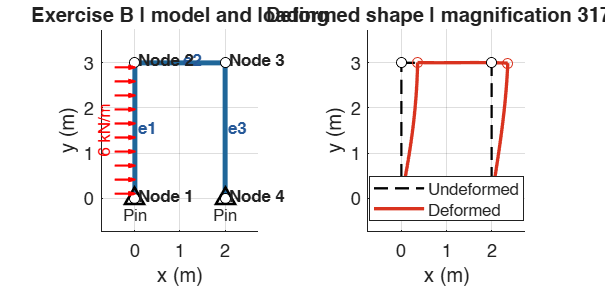

## 18. Classroom investigations and interpretation

Run the baseline model before experimenting. If loads or geometry change, update the analytical-check inputs consistently or skip that section. Suggested investigations: - Double E only: all displacements halve; reactions remain unchanged here. - Increase A only: identify the influence of axial flexibility. - Explain why full K has rigid-body modes but restrained Kff does not. - Reverse a member's node order and transform its local loads consistently; the global physical solution must remain unchanged. Exercise-specific discussion: - Why is the left vertical reaction downward? - Why are base rotations unknown when base moments are zero? - Why must a uniform load generate equivalent nodal moments?

Execute numbered sections in order, or run the whole file. The supporting local functions below are not additional exercise stages.

## LOCAL FUNCTIONS -- supporting routines